**Author: Md Zilan Uddin Saif**

**Exercise 1**

% Define joint variables
syms q4 q5 q6
assume(q4, 'real')
assume(q5, 'real')
assume(q6, 'real')

% Define link lengths
syms d6
assume(d6, 'real')
% Define the A34 transformation matrix
A34 = [cos(q4) 0 -sin(q4) 0;
       sin(q4) 0 cos(q4) 0;
       0 -1 0 0;
       0 0 0 1];
% Display the A34 matrix
disp('A34 Matrix:');

A34 Matrix:


disp(A34);

$$\left(\begin{array}{cccc} \cos\left(q_{4}\right) & 0 & -\sin\left(q_{4}\right) & 0\\ \sin\left(q_{4}\right) & 0 & \cos\left(q_{4}\right) & 0\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Define the A45 transformation matrix
A45 = [cos(q5) 0 sin(q5) 0;
       sin(q5) 0 -cos(q5) 0;
       0 1 0 0;
     0 0 0 1];
% Display the A45 matrix
disp('A45 Matrix:');

A45 Matrix:


disp(A45);

$$\left(\begin{array}{cccc} \cos\left(q_{5}\right) & 0 & \sin\left(q_{5}\right) & 0\\ \sin\left(q_{5}\right) & 0 & -\cos\left(q_{5}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Define the A56 transformation matrix
A56 = [cos(q6) -sin(q6) 0 0;
       sin(q6) cos(q6) 0 0;
       0 0 1 d6;
       0 0 0 1];
% Display the A56 matrix
disp('A56 Matrix:');

A56 Matrix:


disp(A56);

$$\left(\begin{array}{cccc} \cos\left(q_{6}\right) & -\sin\left(q_{6}\right) & 0 & 0\\ \sin\left(q_{6}\right) & \cos\left(q_{6}\right) & 0 & 0\\ 0 & 0 & 1 & d_{6}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Calculate the A36 matrix
A36 = A34 * A45 * A56;
% Display the A36 matrix
disp('A36 Matrix:');

A36 Matrix:


disp(A36);

$$\left(\begin{array}{cccc} \cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)-\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & -\cos\left(q_{6}\right)\,\sin\left(q_{4}\right)-\cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\sin\left(q_{6}\right) & \cos\left(q_{4}\right)\,\sin\left(q_{5}\right) & d_{6}\,\cos\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ \cos\left(q_{4}\right)\,\sin\left(q_{6}\right)+\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)\,\sin\left(q_{4}\right) & \cos\left(q_{4}\right)\,\cos\left(q_{6}\right)-\cos\left(q_{5}\right)\,\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & \sin\left(q_{4}\right)\,\sin\left(q_{5}\right) & d_{6}\,\sin\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ -\cos\left(q_{6}\right)\,\sin\left(q_{5}\right) & \sin\left(q_{5}\right)\,\sin\left(q_{6}\right) & \cos\left(q_{5}\right) & d_{6}\,\cos\left(q_{5}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Define the p3 vector
p3 = [0; 0; 0; 1];

% Display the p3 vector
disp('p3 Vector:');

p3 Vector:


disp(p3);

     0
     0
     0
     1



% Calculate p4 using A34 matrix
p4 = A34 * p3;

% Display p4
disp('p4 Vector:');

p4 Vector:


disp(p4);

$$\left(\begin{array}{c} 0\\ 0\\ 0\\ 1 \end{array}\right)$$


% Calculate p5 using A34 and A45 matrices
p5 = A34 * A45 * p3;

% Display p5
disp('p5 Vector:');

p5 Vector:


disp(p5);

$$\left(\begin{array}{c} 0\\ 0\\ 0\\ 1 \end{array}\right)$$


% Calculate p6 using A34, A45, and A56 matrices
p6 = A34 * A45 * A56 * p3;

% Display p6
disp('p6 Vector:');

p6 Vector:


disp(p6);

$$\left(\begin{array}{c} d_{6}\,\cos\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ d_{6}\,\sin\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ d_{6}\,\cos\left(q_{5}\right)\\ 1 \end{array}\right)$$


% Define the z3 vector
z3 = [0; 0; 1];

% Display z3
disp('z3 Vector:');

z3 Vector:


disp(z3);

     0
     0
     1




% Calculate z4 based on A34 rotation
z4 = A34(1:3, 1:3) * z3;

% Display z4
disp('z4 Vector:');

z4 Vector:


disp(z4);

$$\left(\begin{array}{c} -\sin\left(q_{4}\right)\\ \cos\left(q_{4}\right)\\ 0 \end{array}\right)$$

% Calculate z5 based on A34 and A45 rotations
z5 = A34(1:3, 1:3) * A45(1:3, 1:3) * z3;

% Display z5
disp('z5 Vector:');

z5 Vector:


disp(z5);

$$\left(\begin{array}{c} \cos\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ \sin\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ \cos\left(q_{5}\right) \end{array}\right)$$

% Define the vectors and cross products
cross_product_z3 = cross(z3, p6(1:3) - p3(1:3));
cross_product_z4 = cross(z4, p6(1:3) - p4(1:3));
cross_product_z5 = cross(z5, p6(1:3) - p5(1:3));

% Construct the Jacobian matrix
J = [cross(z3, p6(1:3) - p3(1:3)), cross(z4, p6(1:3) - p4(1:3)), cross(z5, p6(1:3) - p5(1:3));
        z3, z4, z5];

% Simplify the Jacobian matrix
J = simplify(J);

% Display the Jacobian matrix
disp('Geometric Jacobian Matrix (J):');

Geometric Jacobian Matrix (J):


disp(J);

$$\left(\begin{array}{ccc} -d_{6}\,\sin\left(q_{4}\right)\,\sin\left(q_{5}\right) & d_{6}\,\cos\left(q_{4}\right)\,\cos\left(q_{5}\right) & 0\\ d_{6}\,\cos\left(q_{4}\right)\,\sin\left(q_{5}\right) & d_{6}\,\cos\left(q_{5}\right)\,\sin\left(q_{4}\right) & 0\\ 0 & -d_{6}\,\sin\left(q_{5}\right) & 0\\ 0 & -\sin\left(q_{4}\right) & \cos\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ 0 & \cos\left(q_{4}\right) & \sin\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ 1 & 0 & \cos\left(q_{5}\right) \end{array}\right)$$

% Extract the end-effector position vector from A36
Pe = A36(:, 4);

% Display the end-effector position vector
disp('End-Effector Position Vector (Pe):');

End-Effector Position Vector (Pe):


disp(Pe);

$$\left(\begin{array}{c} d_{6}\,\cos\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ d_{6}\,\sin\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ d_{6}\,\cos\left(q_{5}\right)\\ 1 \end{array}\right)$$

% Extract the rotation matrix Phie from A36
Phie = A36(1:3, 1:3);

% Display the rotation matrix Phie
disp('Rotation Matrix Phie:');

Rotation Matrix Phie:


disp(Phie);

$$\left(\begin{array}{ccc} \cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)-\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & -\cos\left(q_{6}\right)\,\sin\left(q_{4}\right)-\cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\sin\left(q_{6}\right) & \cos\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ \cos\left(q_{4}\right)\,\sin\left(q_{6}\right)+\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)\,\sin\left(q_{4}\right) & \cos\left(q_{4}\right)\,\cos\left(q_{6}\right)-\cos\left(q_{5}\right)\,\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & \sin\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ -\cos\left(q_{6}\right)\,\sin\left(q_{5}\right) & \sin\left(q_{5}\right)\,\sin\left(q_{6}\right) & \cos\left(q_{5}\right) \end{array}\right)$$


phi = q4

$$phi = q_{4}$$

theta = q5

$$theta = q_{5}$$

psi = q6

$$psi = q_{6}$$


% Calculate the derivatives
dPexdq4 = diff(Pe(1), q4);
dPexdq5 = diff(Pe(1), q5);
dPexdq6 = diff(Pe(1), q6);

dPeydq4 = diff(Pe(2), q4);
dPeydq5 = diff(Pe(2), q5);
dPeydq6 = diff(Pe(2), q6);

dPezdq4 = diff(Pe(3), q4);
dPezdq5 = diff(Pe(3), q5);
dPezdq6 = diff(Pe(3), q6);

% Construct the Jacobian matrix Jp
Jp = [dPexdq4 dPexdq5 dPexdq6; 
      dPeydq4 dPeydq5 dPeydq6; 
      dPezdq4 dPezdq5 dPezdq6];

% Simplify the Jacobian matrix
Jp = simplify(Jp);

% Display the simplified Jacobian matrix Jp
disp('Jacobian Matrix Jp:');

Jacobian Matrix Jp:


disp(Jp);

$$\left(\begin{array}{ccc} -d_{6}\,\sin\left(q_{4}\right)\,\sin\left(q_{5}\right) & d_{6}\,\cos\left(q_{4}\right)\,\cos\left(q_{5}\right) & 0\\ d_{6}\,\cos\left(q_{4}\right)\,\sin\left(q_{5}\right) & d_{6}\,\cos\left(q_{5}\right)\,\sin\left(q_{4}\right) & 0\\ 0 & -d_{6}\,\sin\left(q_{5}\right) & 0 \end{array}\right)$$

% Calculate the derivatives
dphidq4 = diff(phi, q4);
dphidq5 = diff(phi, q5);
dphidq6 = diff(phi, q6);

dthetadq4 = diff(theta, q4);
dthetadq5 = diff(theta, q5);
dthetadq6 = diff(theta, q6);

dpsidq4 = diff(psi, q4);
dpsidq5 = diff(psi, q5);
dpsidq6 = diff(psi, q6);

% Construct the Jacobian matrix JPhi
JPhi = [dphidq4 dphidq5 dphidq6; 
        dthetadq4 dthetadq5 dthetadq6; 
        dpsidq4 dpsidq5 dpsidq6];

% Simplify the Jacobian matrix
JPhi = simplify(JPhi);

% Display the simplified Jacobian matrix JPhi
disp('Jacobian Matrix JPhi:');

Jacobian Matrix JPhi:


disp(JPhi);

$$\left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$


% Assuming Jp and JPhi are previously defined matrices
% Jp is the Jacobian for end-effector position
% JPhi is the Jacobian for Euler angles

% Combine Jp and JPhi into JA
JA = [Jp; JPhi];

% Convert Euler angles to Jacobian matrix T
T = eul2jac(phi, theta, psi);
disp(T);

$$\left(\begin{array}{ccc} 0 & -\sin\left(q_{4}\right) & \cos\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ 0 & \cos\left(q_{4}\right) & \sin\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ 1 & 0 & \cos\left(q_{5}\right) \end{array}\right)$$


TA=[eye(3),zeros(3,3);zeros(3,3),T];
disp(TA);

$$\left(\begin{array}{cccccc} 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & -\sin\left(q_{4}\right) & \cos\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ 0 & 0 & 0 & 0 & \cos\left(q_{4}\right) & \sin\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ 0 & 0 & 0 & 1 & 0 & \cos\left(q_{5}\right) \end{array}\right)$$


J-(TA*JA) % if matrix full of 0s then we good to go

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

Exercise 3

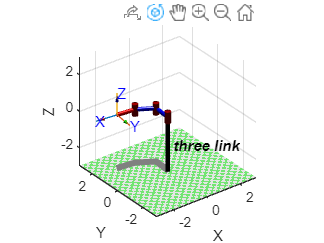

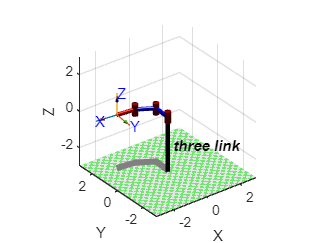

clear
%Three-link planar manipulator
a1=1;
a2=1;
a3=1;
L(1) = Link([0 0 1 0]);
L(2) = Link([0 0 1 0]);
L(3) = Link([0 0 1 0]);
threelink = SerialLink(L, 'name', 'three link');

% Initial configuration 
q0 =[0 pi/4 pi/4]; 
threelink.plot(q0); 
T1=threelink.fkine(q0);
 
% Motions from T1 with a velocity ve=[-1 0] using the Jacobian
% with maximization of the manipulability

a= [a1 a2 a3]';
ve= [-1 0]';

threelink.plot(q0); Delta = 0.07; qcurrent1=q0;

for i=1:50
    % doing it with maximized w 
    qdot=threeLinkJacobian(ve,a,qcurrent1'); 
    qnextl = qcurrent1 + Delta*qdot'; 
    q1=qcurrent1(1);
    q2=qcurrent1(2); 
    q3=qcurrent1(3);

    J=[-a1*sin(q1)-a2*sin(q1+q2)-a3*sin(q1+q2+q3) -a2*sin(q1+q2)-a3*sin(q1+q2+q3) -a3*sin(q1+q2+q3); ...
    a1*cos(q1)+a2*cos(q1+q2)+a3*cos(q1+q2+q3) a2*cos(q1+q2)+a3*cos(q1+q2+q3) a3*cos(q1+q2+q3)];

    w1(i)=sqrt(det(J*J')); 
    qcurrent1 = qnextl;

    threelink.plot(qnextl);
end

% Now, we iterate through the procedure without relying on the threeLinkJacobian function,
% which maximized manipulability. Instead, we directly compute the Jacobian and 
% utilize the pinv(J) operation to determine the next qdot.
figure 
qcurrent2=q0; 
for i=1:50
    % doing it without maximizing w 
    q1=qcurrent2(1); 
    q2=qcurrent2(2); 
    q3=qcurrent2(3);

    J=[-a1*sin(q1)-a2*sin(q1+q2)-a3*sin(q1+q2+q3) -a2*sin(q1+q2)-a3*sin(q1+q2+q3) -a3*sin(q1+q2+q3);
    a1*cos(q1)+a2*cos(q1+q2)+a3*cos(q1+q2+q3) a2*cos(q1+q2)+a3*cos(q1+q2+q3) a3*cos(q1+q2+q3)];

    w2(i)=sqrt(det(J*J')); 
    qdot=pinv(J)*ve;
    qnext2 = qcurrent2 + Delta*qdot';
 
    qcurrent2=qnext2; 
    threelink.plot(qnext2);
end

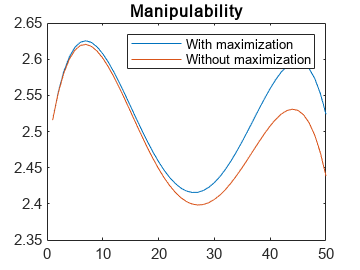


figure
plot(w1) 
hold on 
plot(w2) 
hold off
title('Manipulability')
legend('With maximization','Without maximization')